We will be analyzing the circuit below using nodal analysis

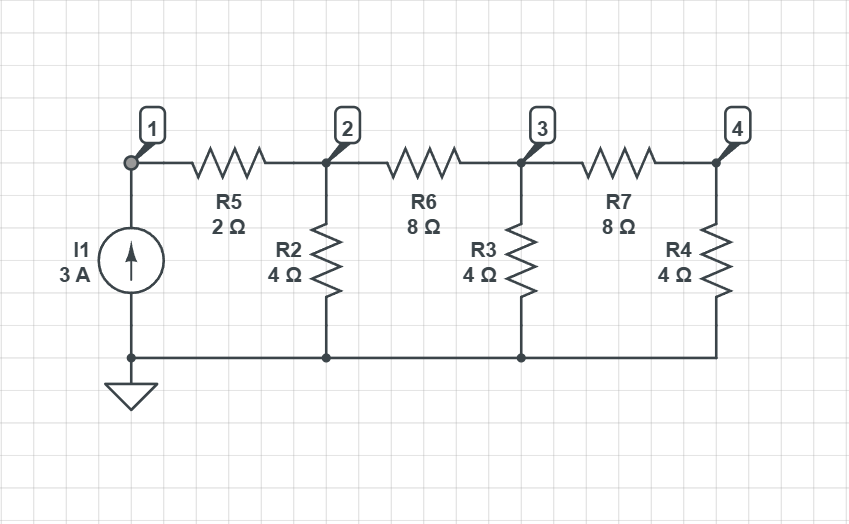

The netlist of this circuit is:

circWuit = Circuit('circuit_1.txt');
N=circuit.list

N =     'I1 0 1 DC 3
     R2 0 2 4
     R3 0 3 4
     R4 0 4 4
     R5 1 2 2
     R6 2 3 8
     R7 3 4 8
     '


While the incidence matrix is:


$$A=\pmatrix{-1 & 0 & 0 & 0 &  1 & 0 & 0 \cr
0 & -1 & 0 & 0 & -1 & 1 & 0 \cr
0 & 0 & -1 & 0 & 0 & -1 & 1 \cr
0 & 0 & 0 & -1 & 0 & 0 & -1}$$


Since Ai=0, we can do:


$$Ai=\pmatrix{-1 & 0 & 0 & 0 &  1 & 0 & 0 \cr
0 & -1 & 0 & 0 & -1 & 1 & 0 \cr
0 & 0 & -1 & 0 & 0 & -1 & 1 \cr
0 & 0 & 0 & -1 & 0 & 0 & -1}\pmatrix{i_1\cr i_2\cr i_3\cr i_4 \cr i_5 \cr i_6 \cr i_7 }=0$$


This mutiplication gives us the following equations:


$$-i_1+i_5=0\\
-i_2-i_5+i_6=0\\
-i_3-i_6+i_7=0\\
-i_4-i_7=0
$$


We also know that the current in each branch is given by Ohms law for closed circuits, so we get:


$$i_1=3,\;i_2=\frac{u_2}{R_2},\;i_3=\frac{u_3}{R_3},\;i_4=\frac{u_4}{R_4},\;i_5=\frac{u_5}{R_5},\;i_6=\frac{u_6}{R_6},\;i_7=\frac{u_7}{R_7}$$


By combining these two we get:


$$-i_1+\frac{u_5}{R_5}=0\\
-\frac{u_2}{R_2}-\frac{u_5}{R_5}+\frac{u_6}{R_6}=0\\
-\frac{u_3}{R_3}-\frac{u_6}{R_6}+\frac{u_7}{R_7}=0\\
-\frac{u_4}{R_4}-\frac{u_7}{R_7}=0
$$


We know 


ELAB.analyze(circuit)
ELAB.evaluate(circuit)
circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=\frac{I_{1}\,\left(R_{2}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{3}\,R_{6}+R_{2}\,R_{4}\,R_{5}+R_{2}\,R_{3}\,R_{7}+R_{2}\,R_{4}\,R_{6}+R_{3}\,R_{4}\,R_{5}+R_{2}\,R_{5}\,R_{7}+R_{3}\,R_{5}\,R_{6}+R_{2}\,R_{6}\,R_{7}+R_{3}\,R_{5}\,R_{7}+R_{4}\,R_{5}\,R_{6}+R_{5}\,R_{6}\,R_{7}\right)}{\sigma_{1}}\\ v_{2}=\frac{I_{1}\,R_{2}\,\left(R_{3}\,R_{4}+R_{3}\,R_{6}+R_{3}\,R_{7}+R_{4}\,R_{6}+R_{6}\,R_{7}\right)}{\sigma_{1}}\\ v_{3}=\frac{I_{1}\,R_{2}\,R_{3}\,\left(R_{4}+R_{7}\right)}{\sigma_{1}}\\ v_{4}=\frac{I_{1}\,R_{2}\,R_{3}\,R_{4}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}+R_{2}\,R_{7}+R_{3}\,R_{6}+R_{3}\,R_{7}+R_{4}\,R_{6}+R_{6}\,R_{7} \end{array}$$

circuit.numerical_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\frac{74}{5}\\ v_{2}=\frac{44}{5}\\ v_{3}=\frac{12}{5}\\ v_{4}=\frac{4}{5} \end{array}\right)$$